file_name = '5hour.xlsx';
fivehour_data = readtable(fullfile('/Users','jakobringberg','Desktop','LINUX_SHARING',file_name));


time_f = 'LocationC.bag';
bag_time = fullfile('/Users','jakobringberg','Desktop','LINUX_SHARING',time_f);

time = rosbag(bag_time);
time = select(time,'Topic','/vectornav');
time_msg = readMessages(time,'DataFormat','struct');
Time = cellfun(@(m) double(m.Header.Stamp.Sec),time_msg);
Time_n = cellfun(@(m) double(m.Header.Stamp.Nsec),time_msg);
Time_n = Time_n./1e9;
Time = Time+Time_n;
Time = Time - Time(1);

yawd    = (table2array(fivehour_data(:,2)));    %deg
pitchd  = (table2array(fivehour_data(:,3)));    %deg
rolld   = (table2array(fivehour_data(:,4)));    %deg
yaw     = yawd.*(pi/180);                       %rad(z) (psi)
pitch   = pitchd.*(pi/180);                     %rad(y) (phi)
roll    = rolld.*(pi/180);                      %rad(x) (theta)
mag_x   = table2array(fivehour_data(:,5));      %unitless (magnitude)
mag_y   = table2array(fivehour_data(:,6));      %unitless (magnitude)
mag_z   = table2array(fivehour_data(:,7));      %unitless (magnitude)
accel_x = table2array(fivehour_data(:,8));      %m/s^2
accel_y = table2array(fivehour_data(:,9));      %m/s^2
accel_z = table2array(fivehour_data(:,10));     %m/s^2
gyro_x  = table2array(fivehour_data(:,11));     %rad/s
gyro_x_deg  = gyro_x.*(180/pi);                 %degree/s
gyro_y  = table2array(fivehour_data(:,12));     %rad/s
gyro_y_deg  = gyro_y.*(180/pi);                 %degree/s
gyro_z  = table2array(fivehour_data(:,13));     %rad/s
gyro_z  = cellfun(@(x) strsplit(x, '*'), gyro_z, 'UniformOutput', false);
gyro_z  = cellfun(@(x) x{1}, gyro_z, 'UniformOutput', false);
gyro_z  = str2double(gyro_z);
gyro_z_deg  = gyro_z.*(180/pi);                 %degree/s

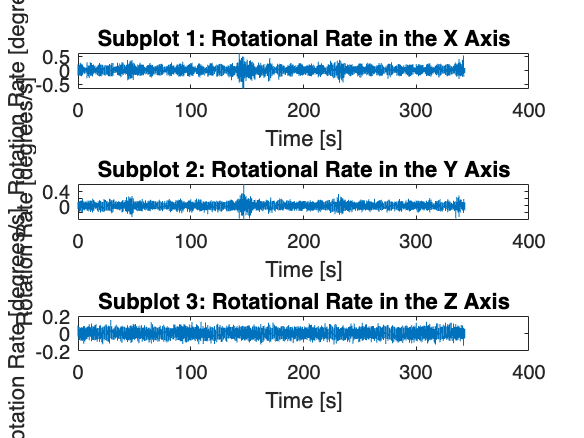

figure(1)
subplot(3,1,1);
plot(Time,gyro_x_deg)
title('Subplot 1: Rotational Rate in the X Axis')
xlabel('Time [s]')
ylabel('Rotation Rate [degrees/s]')

subplot(3,1,2);
plot(Time,gyro_y_deg)
title('Subplot 2: Rotational Rate in the Y Axis')
xlabel('Time [s]')
ylabel('Rotation Rate [degrees/s]')

subplot(3,1,3);
plot(Time,gyro_z_deg)
title('Subplot 3: Rotational Rate in the Z Axis')
xlabel('Time [s]')
ylabel('Rotation Rate [degrees/s]')

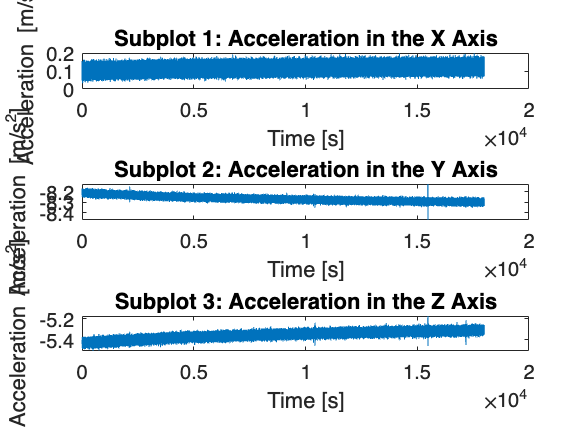

figure(2)
subplot(3,1,1);
plot(Time,accel_x)
title('Subplot 1: Acceleration in the X Axis')
xlabel('Time [s]')
ylabel('Acceleration [m/s^2]')

subplot(3,1,2);
plot(Time,accel_y)
title('Subplot 2: Acceleration in the Y Axis')
xlabel('Time [s]')
ylabel('Acceleration [m/s^2]')

subplot(3,1,3);
plot(Time,accel_z)
title('Subplot 3: Acceleration in the Z Axis')
xlabel('Time [s]')
ylabel('Acceleration [m/s^2]')

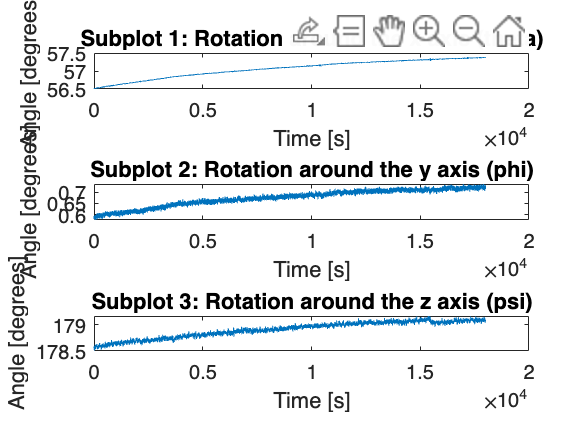

figure(3)
subplot(3,1,3);
plot(Time,yawd)
title('Subplot 3: Rotation around the z axis (psi)')
xlabel('Time [s]')
ylabel('Angle [degrees]')

subplot(3,1,2);
plot(Time,pitchd)
title('Subplot 2: Rotation around the y axis (phi)')
xlabel('Time [s]')
ylabel('Angle [degrees]')

subplot(3,1,1);
plot(Time,rolld)
title('Subplot 1: Rotation around the x axis (theta)')
xlabel('Time [s]')
ylabel('Angle [degrees]')

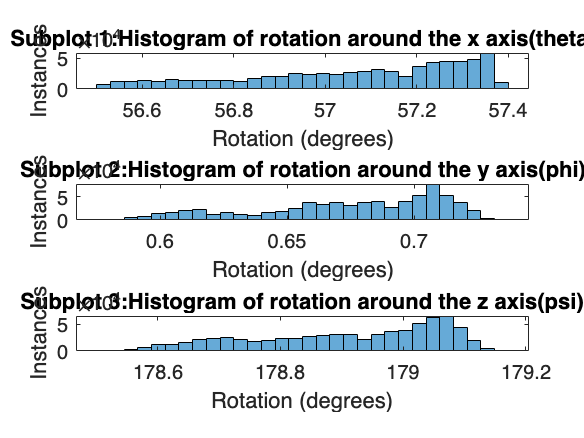

figure(4)
subplot(3,1,1);
histogram(rolld,30)
title('Subplot 1:Histogram of rotation around the x axis(theta)')
xlabel('Rotation (degrees)')
ylabel('Instances')

subplot(3,1,2);
histogram(pitchd,30)
title('Subplot 2:Histogram of rotation around the y axis(phi)')
xlabel('Rotation (degrees)')
ylabel('Instances')

subplot(3,1,3);
histogram(yawd,30)
title('Subplot 3:Histogram of rotation around the z axis(psi)')
xlabel('Rotation (degrees)')
ylabel('Instances')


C11 = cos(roll).*cos(yaw);
C22 = (sin(pitch).*sin(roll).*sin(yaw))+(cos(pitch).*cos(yaw));
C33 = cos(pitch).*cos(roll);
q1 = sqrt((1/4).*(1+C11-C22-C33)); %same as x below but flipped sign q1 is positive but x is negative
q2 = sqrt((1/4).*(1-C11+C22-C33)); %same as y below
q3 = sqrt((1/4).*(1-C11-C22+C33)); %same as z below
q4 = sqrt((1/4).*(1+C11+C22+C33)); %same as w below

%below is method from internet, above is method from class
w = cos(yaw./2).*cos(pitch./2).*cos(roll./2)+sin(yaw./2).*sin(pitch./2).*sin(roll./2);
x = cos(yaw./2).*cos(roll./2).*sin(pitch./2)-sin(yaw./2).*cos(pitch./2).*sin(roll./2);
y = cos(yaw./2).*sin(roll./2).*cos(pitch./2)+sin(yaw./2).*sin(pitch./2).*cos(roll./2);
z = sin(yaw./2).*cos(roll./2).*cos(pitch./2)-cos(yaw./2).*sin(pitch./2).*sin(roll./2);